## Lab 2

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

### Problem 1

This lab explores gamma-ray detection in the atmosphere. The background cosmic rays provide a noise term that follows a Poisson distribution. In order to detect a gamma-ray source, we need to determine the probability that the background gives us a reading as signal-like or more signal-like than our measurement.

Assume that in 1 day, the average cosmic-ray background is 3, and the average number of gamma-rays emitted by the hypothetical source is 13.

Below we first plot what the background distribution looks like for one day.

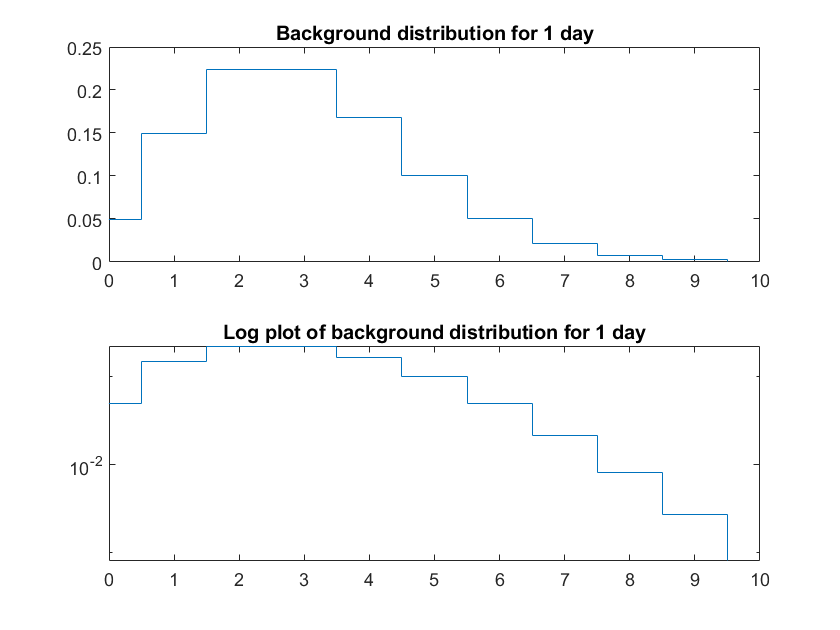

xspan = [0:10];
lambda = 3;
pd = makedist('Poisson',lambda);
subplot(2,1,1)
stairs(xspan-0.5,pdf(pd,xspan))
xlim([0 10])
title('Background distribution for 1 day')

subplot(2,1,2)
stairs(xspan-0.5,pdf(pd,xspan))
set(gca,'YScale','log')
xlim([0 10])
title('Log plot of background distribution for 1 day')

Now we investigate the effect of summing the distribution over a number of days.

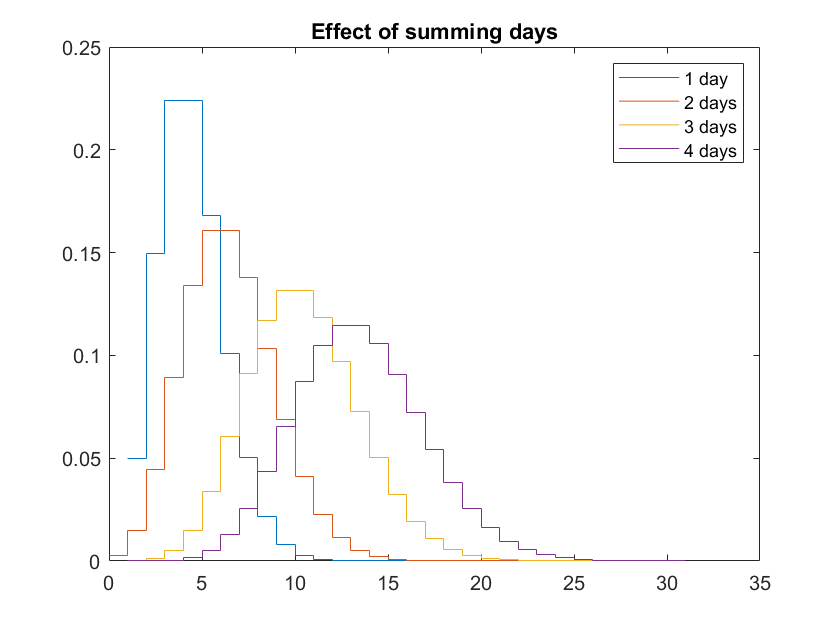

figure
pd_2 = makedist('Poisson',lambda*2);
pd_3 = makedist('Poisson',lambda*3);
pd_4 = makedist('Poisson',lambda*4);
x_sum = [0:30];
stairs(pdf(pd,x_sum))
hold on
stairs(x_sum,pdf(pd_2,x_sum))
stairs(pdf(pd_3,x_sum))
stairs(pdf(pd_4,x_sum))
title('Effect of summing days')
legend('1 day','2 days','3 days','4 days')

The distribution gets wider and is centered around a larger value. This makes sense because as we increase the time interval over which we are observing events, we expect to see more events.

Below we look at the sum over 5 days.

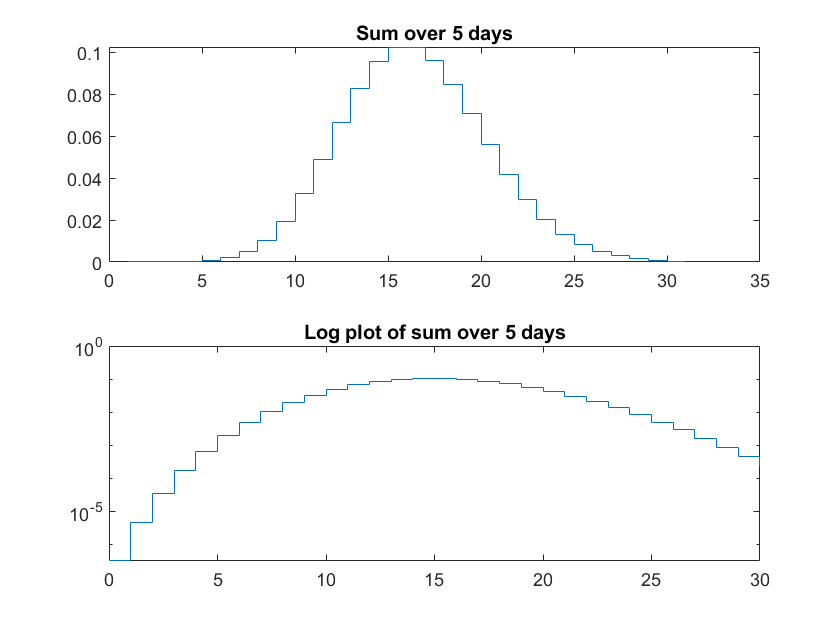

figure
pd_5 = makedist('Poisson',lambda*5);
subplot(2,1,1)
stairs(pdf(pd_5,x_sum))
title('Sum over 5 days')

subplot(2,1,2)
stairs(x_sum,pdf(pd_5,x_sum))
set(gca,'YScale','log')
title('Log plot of sum over 5 days')

The log plot shows the same general shape as the one observed for the 1-day distribution, albeit more spread out. It would make sense for the sum to be a Poisson distribution because we are merely increasing the time interval in which to observe events. The average number of events in the extended period should be proportional to the average number of events in a day.

Mathematically, suppose $X~\mathrm{Poisson}\left(\lambda \right)$. From *proofwiki.org*, the probability generating function of $X$ is given by

$\prod_X \left(s\right)=e^{-\lambda \;\left(1-s\right)}$.

If we have 2 independent time intervals, the resulting probability generating function is


$$\prod_{X+X} \left(s\right)=\prod_X \left(s\right)\prod_X \left(s\right)$$



$$=e^{-\lambda \;\left(1-s\right)} e^{-\lambda \;\left(1-s\right)}$$



$$=e^{-\left(2\lambda \;\right)\left(1-s\right)}$$


This is the probability generating function for a Poisson distribution with a mean of $2\lambda \;$. Therefore any sum of Poisson distributions is also a Poisson distribution with the mean equal to the sum of the means of the original distributions.

We now explore how the probability distribution evolves as we average the days. Plotted below are some averages.

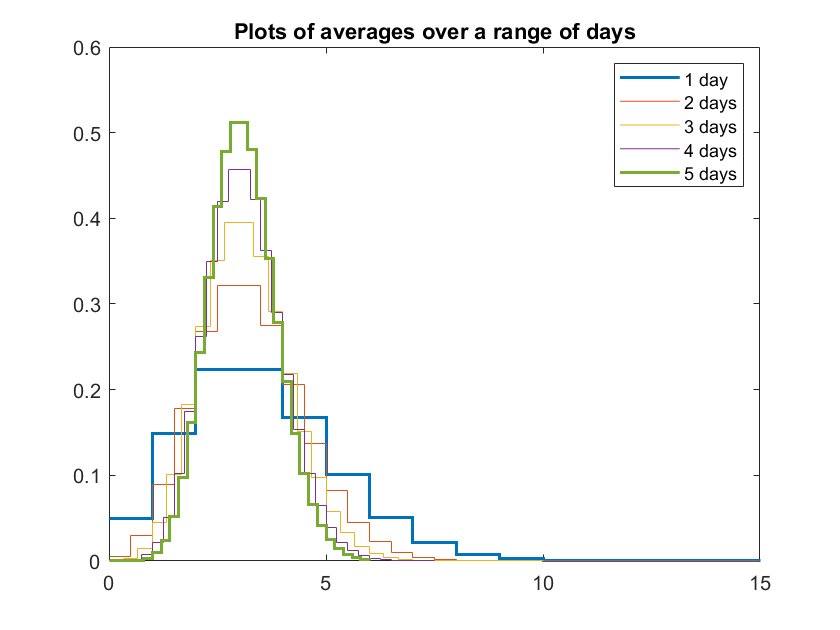

figure
stairs(x_sum,pdf(pd,x_sum),'LineWidth',1.5)
hold on
stairs(x_sum/2,2*pdf(pd_2,x_sum))
stairs(x_sum/3,3*pdf(pd_3,x_sum))
stairs(x_sum/4,4*pdf(pd_4,x_sum))
stairs(x_sum/5,5*pdf(pd_5,x_sum),'LineWidth',1.5)
xlim([0 15])
title('Plots of averages over a range of days')
legend('1 day','2 days','3 days','4 days','5 days')
hold off

The more days over which we take the average, the narrower the distribution becomes. The mean remains the same but we can see that the standard deviation decreases. To generate the plots above, we shrank the x-axes and extended the y-axes to maintain normalization. Doing this caused the distri